# PV Models

% Created by: Giacomo Mastroddi, September 2023
clearvars; close all;

par = get_car_param();

#### PV power vs ambient temperature

T_STC = par.theta_STC - 273.15; % [°]
G = par.G_0; % [W/m^2]
T_amb = linspace(0,45,45); % [°]
v_wind = 6; % [m/s]

PVpower = par.A_PV * G * par.eta_PV_tot;

PVpower_basic           = PVpower*(1 - par.lambda_PV*T_amb);

[T_cell_Faiman, T_module_Faiman] = theta_Faiman(G, T_amb, v_wind, par.eta_PV);
PVpower_Faiman          = PVpower*(1 - par.lambda_PV*(T_module_Faiman - T_STC));

[T_cell_Sandia, T_module_Sandia] = theta_Sandia(G, T_amb, v_wind, "glass-cell-polymer", "open rack");
PVpower_Sandia_openRack = PVpower*(1 - par.lambda_PV*(T_module_Sandia - T_STC));

PVpower_NOCT            = PVpower*(1 - par.lambda_PV*(theta_cell_NOCT(G, T_amb, v_wind, par.eta_PV) - T_STC));

Plots

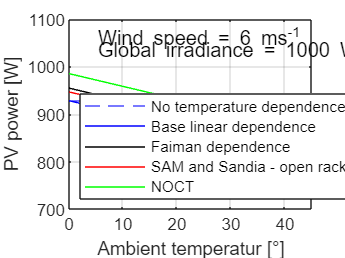

figure
yline(PVpower,'--b', 'DisplayName', 'No temperature dependence')
hold on
plot(T_amb,PVpower_basic,'b', 'DisplayName', 'Base linear dependence')
plot(T_amb,PVpower_Faiman,'k', 'DisplayName', 'Faiman dependence')
plot(T_amb,PVpower_Sandia_openRack,'r', 'DisplayName', 'SAM and Sandia - open rack')
plot(T_amb,PVpower_NOCT,'g', 'DisplayName', 'NOCT')

clickableLegend
legend('Location', 'southwest')

xlabel("Ambient temperatur [°]")
ylabel("PV power [W]")
xlim([0 max(T_amb)])
ylim([G-300 G+100])
grid on
box on
textName = ['Wind speed = ', num2str(v_wind), ' ms^{-1}'];
text(5,G+60,textName);
textName = ['Global irradiance = ', num2str(G), ' Wm^{-2}'];
text(5,G+35,textName);
hold off

#### PV power vs wind speed

figure
T_amb = 35; % [°]
v_wind = linspace(1,10,20); % [m/s]

PVpower_basic           = PVpower*(1 - par.lambda_PV*T_amb);

[T_cell_Faiman, T_module_Faiman] = theta_Faiman(G, T_amb, v_wind, par.eta_PV);
PVpower_Faiman          = PVpower*(1 - par.lambda_PV*(T_module_Faiman - T_STC));

[T_cell_Sandia, T_module_Sandia] = theta_Sandia(G, T_amb, v_wind, "glass-cell-polymer", "open rack");
PVpower_Sandia_openRack = PVpower*(1 - par.lambda_PV*(T_module_Sandia - T_STC));

PVpower_NOCT            = PVpower*(1 - par.lambda_PV*(theta_cell_NOCT(G, T_amb, v_wind, par.eta_PV) - T_STC));

Plots

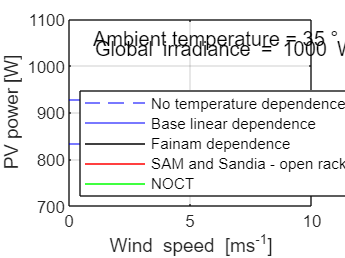

yline(PVpower,'--b', 'DisplayName', 'No temperature dependence')
hold on
yline(PVpower_basic,'b', 'DisplayName', 'Base linear dependence')
plot(v_wind,PVpower_Faiman,'k', 'DisplayName', 'Fainam dependence')
plot(v_wind,PVpower_Sandia_openRack,'r', 'DisplayName', 'SAM and Sandia - open rack')
plot(v_wind,PVpower_NOCT,'g', 'DisplayName', 'NOCT')

clickableLegend
legend('Location', 'southwest')

xlabel("Wind speed [ms^{-1}]")
ylabel("PV power [W]")
xlim([0 max(v_wind)])
ylim([G-300 G+100])
grid on
box on
textName = ['Ambient temperature = ', num2str(T_amb), ' °'];
text(1,G+60,textName);
textName = ['Global irradiance = ', num2str(G), ' W/m^2'];
text(1,G+35,textName);
hold off